# Dynamic Link Analysis

This example demonstrates how to set up a satellite communications downlink between one satellite and one ground station.  The example calculates the times over the course of a day during when the satellite can communicate with the ground station.

## Create Satellite Scenario

Use `satelliteScenario` to create a satellite scenario named `sc`.  Use `datetime` to define the start time and stop time of the scenario.  Set the sample time to 60 seconds.  To learn the `satelliteScenario` syntax, type `doc satelliteScenario` at the MATLAB command line.

startTime = datetime(2020,8,19,20,55,0); % 19 August 2020 8:55 PM UTC, value-only argument
stopTime = startTime + days(1);          % 20 August 2020 8:55 PM UTC, value-only argument
sampleTime = 60;                         % seconds, value-only argument
sc = satelliteScenario(startTime,stopTime,sampleTime);

## Launch Satellite Scenario Viewer

Use `satelliteScenarioViewer` to launch a Satellite Scenario Viewer named `vwr`.

vwr = satelliteScenarioViewer(sc);

## Add Satellite to Scenario

Use `satellite` to add a satellite with variable name `sat` to the scenario `sc` by specifying its Keplerian orbital elements corresponding to the scenario start time.  Specify the name of the satellite as "Satellite", and the orbit propagator as "two-body-keplerian".  To learn the `satellite` syntax, type `doc satellite` at the MATLAB command line.

semiMajorAxis = 1e7;               % meters, value-only argument
eccentricity = 0.2;                % unitless, value-only argument
inclination = 0;                   % degrees, value-only argument
rightAscensionOfAscendingNode = 0; % degrees, value-only argument
argumentOfPeriapsis = 0;           % degrees, value-only argument
trueAnomaly = 0;                   % degrees, value-only argument
orbProp = "two-body-keplerian";    % name-value pair
satName = "Satellite";             % name-value pair
sat = satellite(sc, ...
  semiMajorAxis, ...
  eccentricity, ...
  inclination, ...
  rightAscensionOfAscendingNode, ...
  argumentOfPeriapsis, ...
  trueAnomaly, ...
  OrbitPropagator=orbProp, ...
  Name=satName);

## Add Gimbal to Satellite

Use `gimbal` to add a gimbal with variable name `gimbalSat` to the satellite `sat`.  The gimbal holds the transmitter antenna.  The mounting location is specified in cartesian coordinates in the body frame of the satellite, which is defined by $\left(\hat{x}_S,\hat{y}_S,\hat{z}_S\right)$, where $\hat{x}_S$, $\hat{y}_S$ and $\hat{z}_S$ are the roll, pitch and yaw axes respectively, of the satellite.  The mounting location of the gimbal that holds the transmitter is $\hat{y}_S + 2\hat{z}_S$ meters, as illustrated in the diagram below.

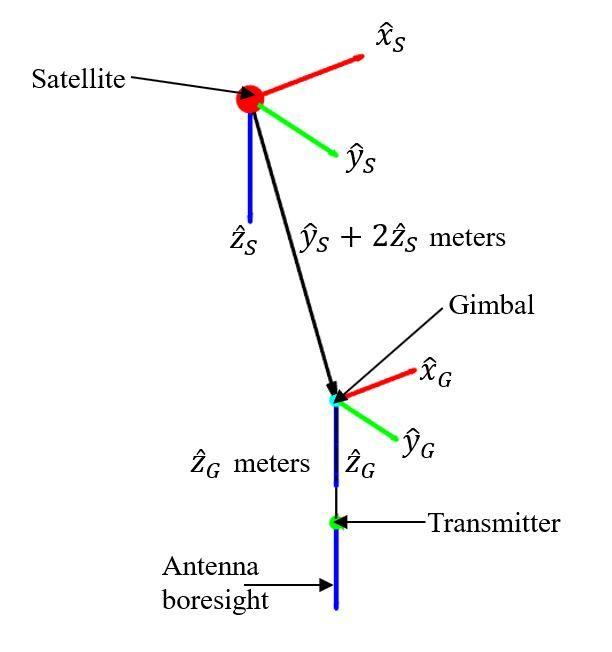the 

gimbalSat = gimbal(sat, ...
  MountingLocation=[0;1;2]);  % meters

## Add Transmitter to Satellite Gimbal

Use `transmitter` to add a transmitter with variable name `satTx` to the gimbal `gimbalSat`.  The mounting location of the transmitting antenna with respect to the gimbal is $\hat{z}_G$ meters, where $\left(\hat{x}_G, \hat{y}_G, \hat{z}_G\right)$ define the body frame of the gimbal.  The boresight of the antenna is aligned with $\hat{z}_G$.  The satellite transmits with a power of 15 dBW.  The transmitter on board the satellite downlinks at a frequency of 10 GHz.  The name of the transmitter is "Satellite Transmitter".  To learn the `transmitter` syntax, type `doc transmitter` at the MATLAB command line.

txMountLoc = [0;0;1];              % Zg meters, name-value pair
txFreq = 10e9;                     % Hz, name-value pair
txPower = 15;                      % dBW, name-value pair
txName = "Satellite Transmitter";  % name-value pair
% Add transmitter with variable name satTx to satellite gimbal gimbalSat.
% Hint:  Type "doc transmitter" in the MATLAB Command Window.  Look for
% "transmitter" from Satellite Communications Toolbox, and see the "Syntax"
% section.
satTx = transmitter(gimbalSat, ...
  MountingLocation=txMountLoc, ...
  Frequency=txFreq, ...         
  Power=txPower, ...
  Name=txName);

When you are done with this section and run it, display the `gimbalSat` variable to ensure that it contains a nonempty Transmitters property.

## Add Antenna to Satellite Transmitter

Use `gaussianAntenna` to set the dish diameter of the antenna of the satellite transmitter `satTx`  to 0.5 m.  A Gaussian antenna has a radiation pattern that peaks at its boresight and decays radial-symmetrically based on a Gaussian distribution while moving away from boresight, as shown in the diagram below.  It also has no sidelobes.  The peak gain is a function of the dish diameter and aperture efficiency.  To learn the `gaussianAntenna` syntax, type `doc gaussianAntenna` at the MATLAB command line.

The call to `gaussianAntenna` does not need an output argument, because the antenna object is not used by itself for the remainder of this example.

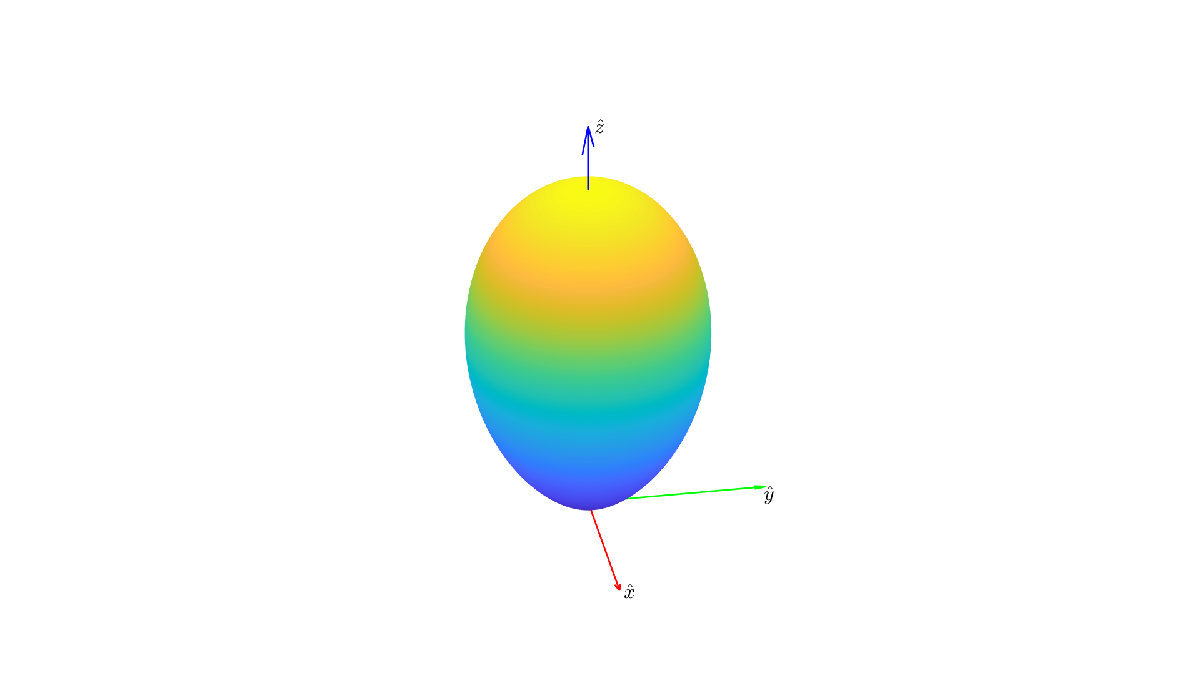

txDishDiam = 0.5;  % meters, name-value pair
% Add gaussian antenna to satellite transmitter satTx.  Hint:  Type "doc
% gaussianAntenna" in the MATLAB Command Window, and see the "Syntax"
% section.
gaussianAntenna(satTx, ...
  DishDiameter=txDishDiam);

When you are done with this section and run it, display the `satTx` variable to ensure that it has a nonempty Antenna property.

## Add Ground Station

Use `groundStation` to add a ground station named `gs` to the scenario `sc`.  Provide the latitude and longitude coordinates of the ground station.  Give the ground station a name called "Ground Station".  To learn the `groundStation` syntax, type `doc groundStation` at the MATLAB command line.

latitude = 12.9;  % degrees, value-only argument
longitude = 77.7; % degrees, value-only argument
gsName = "Ground Station";  % name-value pair
gs = groundStation(sc, ...
  latitude, ...
  longitude, ...
  Name=gsName);

## Add Gimbal to the Ground Station

Use `gimbal` to add a gimbal to the ground station `gs`.  The gimbal at the ground station holds a receiver. The gimbal is located 5 meters above its ground station, as illustrated in the diagram below. Consequently, its mounting location is $-5\hat{z}_{GS}$ meters, where $\left(\hat{x}_{GS}, \hat{y}_{GS}, \hat{z}_{GS}\right)$ define the body axis of the ground station.  $\hat{x}_{GS}$, $\hat{y}_{GS}$ and $\hat{z}_{GS}$ always point North, East and down respectively.  Therefore, the $\hat{z}_{GS}$ component of the gimbal is -5 meters so that they are placed above the ground station and not below.  Furthermore, by default, the mounting angles of the gimbal are such that their body axes $\left(\hat{x}_G, \hat{y}_G, \hat{z}_G\right)$ are aligned with the parent (in this case, the ground station) body axes $\left(\hat{x}_{GS}, \hat{y}_{GS}, \hat{z}_{GS}\right)$.  As a result, when the gimbal is not steered, its $\hat{z}_{G}$ axis points straight down, and so does the antenna attached to it using default mounting angles as well.  Therefore, set the mounting pitch angle to 180 degrees, so that $\hat{z}_G$ points straight up when the gimbal is not steered.

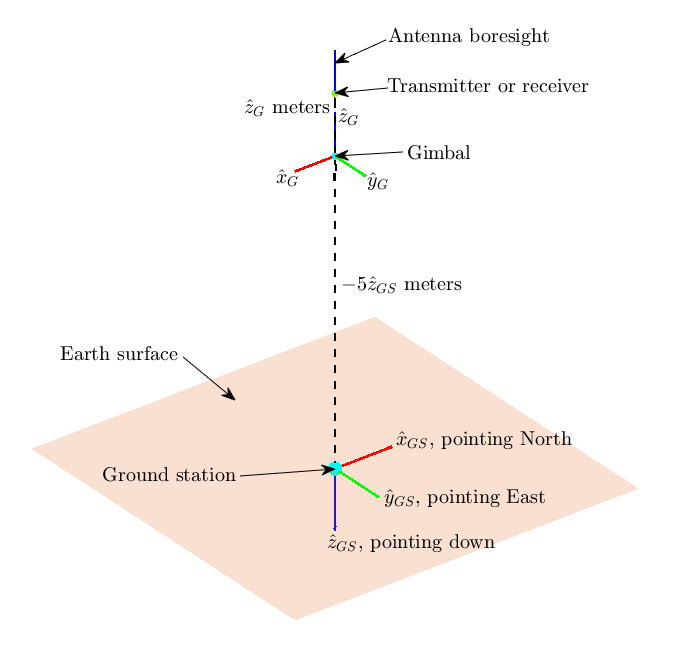

gimbalGs = gimbal(gs, ...
  MountingAngles=[0;180;0], ... % degrees
  MountingLocation=[0;0;-5]);   % meters

## Add Receiver to Ground Station Gimbal

Use `receiver` to add a receiver with variable name `gsRx` to the ground station gimbal `gimbalGs` to receive downlink data from the satellite.  The receiver gain to noise temperature ratio is 3 dB/K and the required Eb/No is 1 dB.  The mounting location of the receiver antenna is $\hat{z}_G$ meters with respect to the gimbal.  Give the ground station the name of "Ground Station Receiver"`.`  To learn the `receiver` syntax, type `doc receiver` at the MATLAB command line.

gsMountLoc = [0;0;1];  % Zg meters, name-value pair
GoverT = 3;            % dB/K, name-value pair
rqdEbNo = 1;           % dB, name-value pair
rxName = "Ground Station Receiver";  % name-value pair
% Add receiver with variable name gsRx to ground station gimbal gimbalGs.
% Hint:  Type "doc receiver" in the MATLAB Command Window.  Look for
% "receiver" from Satellite Communications Toolbox, and see the "Syntax"
% section.
gsRx = receiver(gimbalGs, ...
  MountingLocation=gsMountLoc, ...
  GainToNoiseTemperatureRatio=GoverT, ... 
  RequiredEbNo=rqdEbNo, ...
  Name=rxName);

When you are done with this section and run it, display the `gimbalGs` variable to ensure that it has a nonempty Receivers property.

Use `gaussianAntenna` to set the dish diameter of the receiver antenna to 2 m.

rxDishDiam = 2;  % meters, name-value pair
% Add gaussian antenna to ground station receiver gsRx.  Hint:  Type "doc
% gaussianAntenna" in the MATLAB Command Window, and see the "Syntax"
% section.
gaussianAntenna(gsRx, ...
  DishDiameter=rxDishDiam);

When you are done with this section and run it, display the `gsRx` variable to ensure that it has a nonempty Antenna property.

## Set Tracking Targets for Gimbals

For the best link quality, the antennas must continuously point at their respective targets.  The gimbals can be steered independent of their parents (satellite or ground station), and configured to track other satellites and ground stations.  Use `pointAt` to set the tracking target for the gimbals so that:

- The satellite transmitter antenna points at the ground station

- The ground station receiver antenna points at the satellite

To learn the `pointAt` syntax, type `doc pointAt` at the MATLAB command line.

pointAt(gimbalSat,gs);
% Point the ground station gimbal gimbalGs to the satellite sat.  Hint:
% Type "doc pointAt" at the MATLAB Command Window, and see the "Syntax"
% section.
% Use value-only arguments.
pointAt(gimbalGs,sat);

When a target for a gimbal is set, its $\hat{z}_G$ axis will track the target.  Since the antenna is on $\hat{z}_G$ and its boresight is aligned with $\hat{z}_G$, the antenna will also track the desired target.

## Add Link Analysis and Visualize Scenario

Use `link` to add link analysis with variable name `lnk` from the satellite transmitter `satTx` to the ground station receiver `gsRx`.

% Add a link analysis with variable name lnk from the satellite
% transmitter satTx to the ground station receiver gsRx.  Hint:  Type "doc
% link" in the MATLAB Command Window.  Look for "link" from Satellite
% Communications Toolbox, and see the "Syntax" section.
% Use value-only arguments.
lnk = link(satTx,gsRx);

The Satellite Scenario Viewer automatically updates to display the entire scenario.  Use the viewer as a visual confirmation that the scenario has been set up correctly.  The line from satellite to ground station represents the link and confirms that the link is closed.

When you are done with this section and run it, you should see a Satellite Scenario Viewer that looks like this:

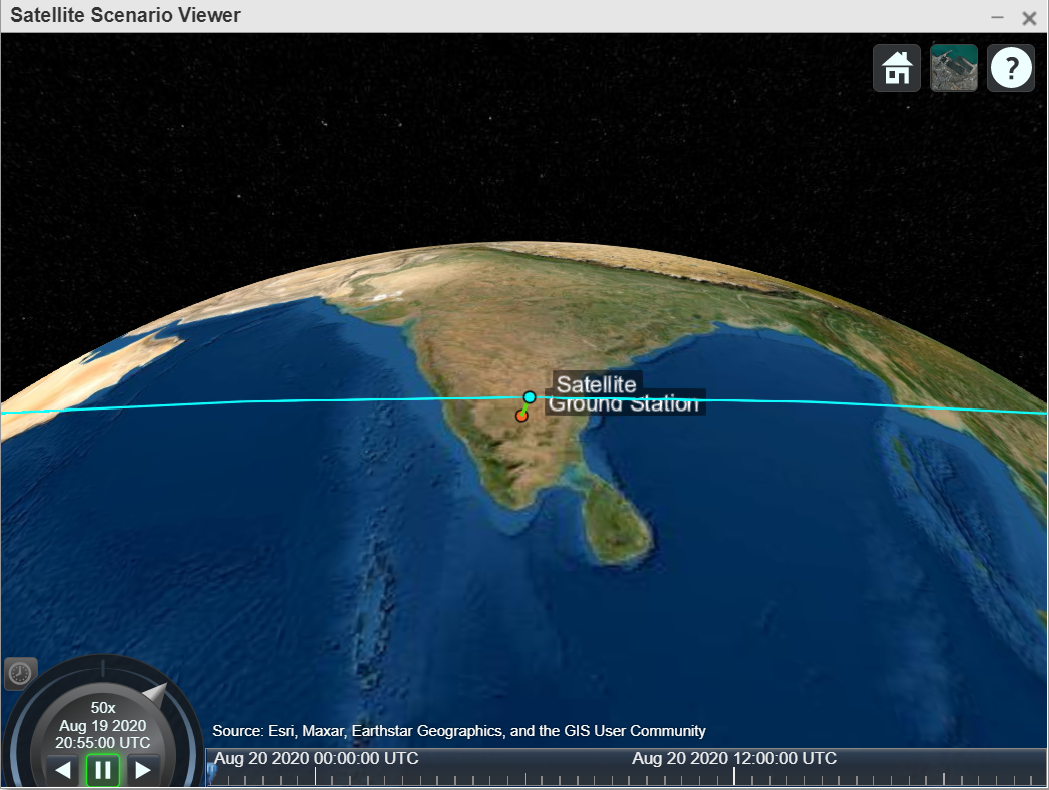

## Determine Times When Link is Closed and Visualize Link Closures

Use the `linkIntervals` method to determine the times when the link is closed.  The `linkIntervals` method outputs a table of the start and stop times of link closures that represent the intervals during which the satellite can send data to the ground station.  Source and Target are the first and last nodes in the link.  If one of Source or Target is on a satellite, StartOrbit and EndOrbit provide the orbit count of the source or target satellite that they are attached directly or via gimbals, starting from the scenario start time.  If both Source and Target are attached to a satellite, StartOrbit and EndOrbit provide the orbit count of the satellite to which Source is attached.  

linkIntervals(lnk)

ans = 8×8 table
            Source                      Target              IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    _______________________    _________________________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite Transmitter"    "Ground Station Receiver"          1           19-Aug-2020 20:55:00    19-Aug-2020 21:07:00       720          1            1    
    "Satellite Transmitter"    "Ground Station Receiver"          2           19-Aug-2020 23:43:00    20-Aug-2020 00:15:00      1920          2            2    
    "Satellite Transmitter"    "Ground Station Receiver"          3

Use `play` to visualize the scenario simulation from its start time to stop time.  The line from satellite to ground station appears whenever the link is closed.

% Set the viewer camera (not satellite camera) position for better scenario
% viewing
camLat = latitude;   % camera latitude, deg
camLon = longitude;  % camera longitude, deg
camAlt = 2e7;        % camera altitude, m
campos(vwr,camLat,camLon,camAlt);

speedMultiplier = 1000;  % name-value pair
play(sc, ...
  PlaybackSpeedMultiplier=speedMultiplier);